clear; clc; close all

`Alice and Bob generate same Key using Quantum Key Distribution`

`If Eavesdropper is present Alice and Bob can detect eaves presence with a `

`probability of ``P(eaves's presence) = 1 - (3/4)^n`` where n = no.of bits`

[alice_key, bob_key] = QKD(100,0);
disp(alice_key)

  Columns 1 through 20

     0     1     0     0     0     1     0     1     1     1     0     0     0     0     0     0     0     0     0     0

  Columns 21 through 40

     1     1     1     0     0     1     1     1     1     0     1     0     1     0     0     1     0     1     1     1

  Columns 41 through 45

     1     0     1     1     0



disp(bob_key)

  Columns 1 through 20

     0     1     0     0     0     1     0     1     1     1     0     0     0     0     0     0     0     0     0     0

  Columns 21 through 40

     1     1     1     0     0     1     1     1     1     0     1     0     1     0     0     1     0     1     1     1

  Columns 41 through 45

     1     0     1     1     0



`Alice side`

`Encrypting the plain text using key`

fid=fopen('plain.txt','rt');
p_tx=transpose(fread(fid)); 
fclose(fid);
disp(char(p_tx))

Quantum key distribution (QKD) is a secure communication method which implements a cryptographic protocol involving components of quantum mechanics. It enables two parties to produce a shared random secret key known only to them, which can then be used to encrypt and decrypt messages. It is often incorrectly called quantum cryptography, as it is the best-known example of a quantum cryptographic task.

An important and unique property of quantum key distribution is the ability of the two communicating users to detect the presence of any third party trying to gain knowledge of the key. This results from a fundamental aspect of quantum mechanics: the process of measuring a quantum system in general disturbs the system. A third party trying to eavesdrop on the key must in some way measure it, thus introducing detectable anomalies. By using quantum superpositions or quantum entanglement and transmitting information in quantum states, a communication system can be implemented that detects ea


encrypt('plain.txt', 'cipher.txt', alice_key);

fid=fopen('cipher.txt','rt');
c_tx=transpose(fread(fid)); 
fclose(fid);
disp(char(c_tx))

µoãÇC ±Ä±jíÑââiF2 Ïø0fÉ'T8ùv J=½Êdï1(­{þÑOt»Ó±fêÍï kF4 ÄNjX%­d XÊ=ºÁq»=7¡~þÑp»ÉþlòåösY
2gÇÊOhS.·cs8èÉt®<0­.òÑFa½Þâ^#×ÑÌîî}C/ ÞfO?°rs1èÈs 6&¥.·ÁFa±Ù±bðÁæ oL9tÇÂ[ÀlS$®y V2±u r-¥cV·ÅFi¼òm¾Ñîî<JD)sÍ[V'X%ºeyI~©Öeï6&²w
ãCe §Üöp°¥ÿ u:tÇ[KdR9«rcM'èÛ`£>!àöÜZuôÞã	sêÊùálVH|aVÀnNk­e;»Ì,¤<2®.ïÓCp±þ#ÿþárZ	|cÐV`O*©iZÊ*©ËjáXü®.úÂArµÓåPbðÁÌþîuZ|pÆGsDk¶q H?¦Ìt¢r ¹.þÁZr¶Èålðø hJD=bÅV'R-ùch\Ê*¿×!¬=(µ`ôÓZi³äfìÖÌÿï<J9cJ'M9¼deW;è×gï3<àzþÀJ µÏå	#ê×âî{Õ[|gÀiR<µrd^~§Þ!»:e«k¹zh§ãpëÉø z@	|aÇÏLfP.·caUÊ?»Èd¬&Ö*¦.âÓ@t¹ü`öÄâãoÏ4eÇÙ	MbN8ùxf;©Ët½;"àoZæÇOn¡Ð±zíÑæ u9nÛNÀcT8­br[~¼Ðdï!6´k¹o ¼Ôã#îÄÿù<]5nMÀb\=¼ddK.è×oï& àeîCu ø#íÊî kVD1eÚP'T?õ7tQ-èÑo» !µmùÕd ØòbüÉ«árB0iÚU¢~>ª~n^Ê/½Ùo»'e³{
òÀ^o ½Éømíù mN
(uLfS,µrm\*èÙo«r7¡`	úÛZtºÚ±møÊæáh@
|i
WiI>´7sM*­Ë-ï3Ö&¯câÜGc Ôþ#íÜÿåqÕL2 Ì[KwQ.´rnM:èÌi®&Ö!¥zôÆ] µËôgìÊûérDfÇÝGÀkX=¼{ V~­Ùwª!7¯~
þÜI §óoñÒÌê ]=iJbN#¶{dÊ?èÓd¶r$®.ò^r°Èòg¾Ñêô<\D;uÛLbX/ùco;èËd¬' à&¹× ,S ÕôPfÿÓøän_9rÇÁQÀiRk°yfV3©Ìh <Ö$¢aãGtZøþkû×âóyÕA|sÊP'V. 7iJÊ.§Ër¦0 àoóMo¹Èÿ`ÿÑäî<\D=bÛG)7Ae;«Ís¦&e¯hZòÜMr
¤Éøm¾Ñêô<\/ ÜLrPk²ry7

`Hiding the cipher text in the image in Hilbert fractal pattern`

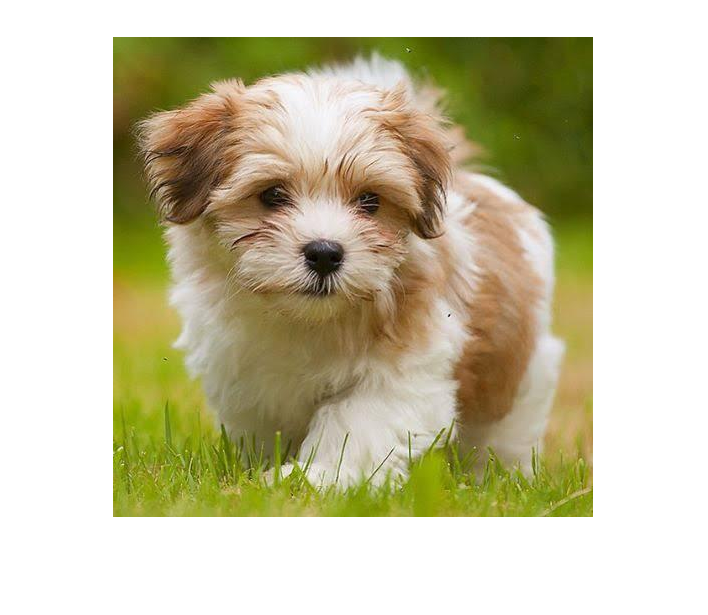

i = imread('dog.jpeg');
imshow(i)

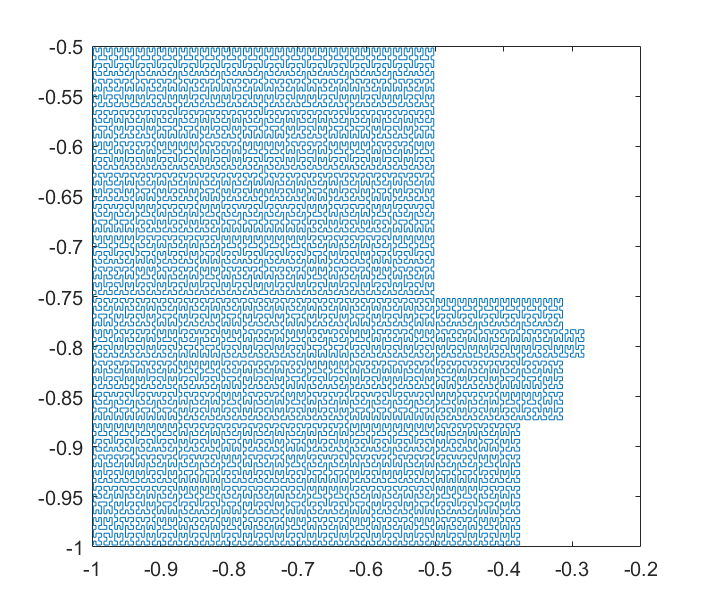

txt_steno_im_h('dog.jpeg','cipher.txt','steno.png');

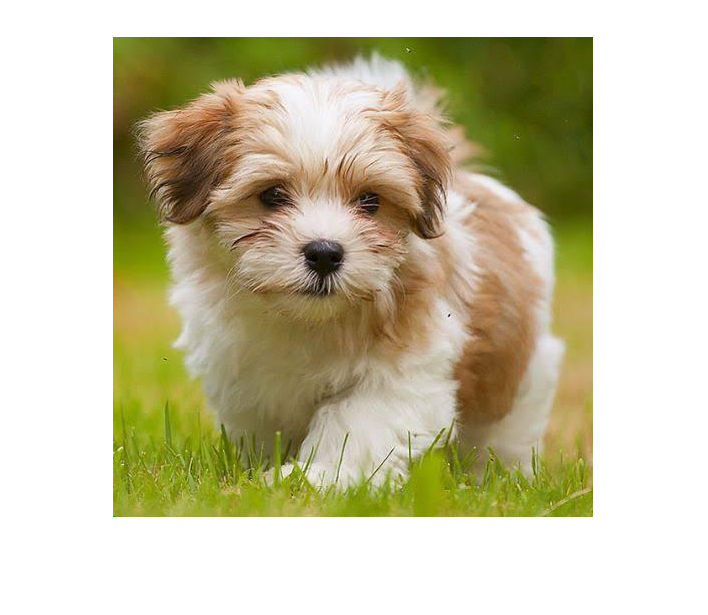

j = imread('steno.png');
imshow(j)

`Bob side`

`Extracting the hidden cipher test from steno image`

im_steno_txt_h('steno.png','cipher_rx.txt');

fid=fopen('cipher_rx.txt','rt');
c_rx=transpose(fread(fid)); 
fclose(fid);
disp(char(c_rx))

µoãÇC ±Ä±jíÑââiF2 Ïø0fÉ'T8ùv J=½Êdï1(­{þÑOt»Ó±fêÍï kF4 ÄNjX%­d XÊ=ºÁq»=7¡~þÑp»ÉþlòåösY
2gÇÊOhS.·cs8èÉt®<0­.òÑFa½Þâ^#×ÑÌîî}C/ ÞfO?°rs1èÈs 6&¥.·ÁFa±Ù±bðÁæ oL9tÇÂ[ÀlS$®y V2±u r-¥cV·ÅFi¼òm¾Ñîî<JD)sÍ[V'X%ºeyI~©Öeï6&²w
ãCe §Üöp°¥ÿ u:tÇ[KdR9«rcM'èÛ`£>!àöÜZuôÞã	sêÊùálVH|aVÀnNk­e;»Ì,¤<2®.ïÓCp±þ#ÿþárZ	|cÐV`O*©iZÊ*©ËjáXü®.úÂArµÓåPbðÁÌþîuZ|pÆGsDk¶q H?¦Ìt¢r ¹.þÁZr¶Èålðø hJD=bÅV'R-ùch\Ê*¿×!¬=(µ`ôÓZi³äfìÖÌÿï<J9cJ'M9¼deW;è×gï3<àzþÀJ µÏå	#ê×âî{Õ[|gÀiR<µrd^~§Þ!»:e«k¹zh§ãpëÉø z@	|aÇÏLfP.·caUÊ?»Èd¬&Ö*¦.âÓ@t¹ü`öÄâãoÏ4eÇÙ	MbN8ùxf;©Ët½;"àoZæÇOn¡Ð±zíÑæ u9nÛNÀcT8­br[~¼Ðdï!6´k¹o ¼Ôã#îÄÿù<]5nMÀb\=¼ddK.è×oï& àeîCu ø#íÊî kVD1eÚP'T?õ7tQ-èÑo» !µmùÕd ØòbüÉ«árB0iÚU¢~>ª~n^Ê/½Ùo»'e³{
òÀ^o ½Éømíù mN
(uLfS,µrm\*èÙo«r7¡`	úÛZtºÚ±møÊæáh@
|i
WiI>´7sM*­Ë-ï3Ö&¯câÜGc Ôþ#íÜÿåqÕL2 Ì[KwQ.´rnM:èÌi®&Ö!¥zôÆ] µËôgìÊûérDfÇÝGÀkX=¼{ V~­Ùwª!7¯~
þÜI §óoñÒÌê ]=iJbN#¶{dÊ?èÓd¶r$®.ò^r°Èòg¾Ñêô<\D;uÛLbX/ùco;èËd¬' à&¹× ,S ÕôPfÿÓøän_9rÇÁQÀiRk°yfV3©Ìh <Ö$¢aãGtZøþkû×âóyÕA|sÊP'V. 7iJÊ.§Ër¦0 àoóMo¹Èÿ`ÿÑäî<\D=bÛG)7Ae;«Ís¦&e¯hZòÜMr
¤Éøm¾Ñêô<\/ ÜLrPk²ry7

`Decrypt the cipher text using key`

decrypt('cipher_rx.txt','plain_rx.txt', bob_key);

fid=fopen('plain_rx.txt','rt');
p_rx=transpose(fread(fid)); 
fclose(fid);
disp(char(p_rx))

Quantum key distribution (QKD) is a secure communication method which implements a cryptographic protocol involving components of quantum mechanics. It enables two parties to produce a shared random secret key known only to them, which can then be used to encrypt and decrypt messages. It is often incorrectly called quantum cryptography, as it is the best-known example of a quantum cryptographic task.

An important and unique property of quantum key distribution is the ability of the two communicating users to detect the presence of any third party trying to gain knowledge of the key. This results from a fundamental aspect of quantum mechanics: the process of measuring a quantum system in general disturbs the system. A third party trying to eavesdrop on the key must in some way measure it, thus introducing detectable anomalies. By using quantum superpositions or quantum entanglement and transmitting information in quantum states, a communication system can be implemented that detects ea

sum(p_rx == p_tx)

ans = 2376